# Lab 1

## Problema 1

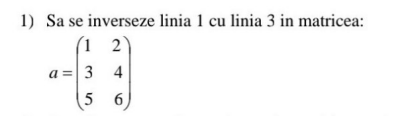

a=[1 2; 3 4; 5 6;];
b=a(3,:);
a(3,:)=a(1,:);
a(1,:)=b;
a

a =      5     6
     3     4
     1     2


## Problema 2

a=[1 2 3; 4 5 6;];
b=a(:,2);
a(:,2)=a(:,3);
a(:,3)=b;
a

a =      1     3     2
     4     6     5


## Problema 3

v=[1 2 3 4 5 7 11 13];
a=v(1,3);
b=v(1,5);
c=v(1,6);
d=v(1,7);
a

a = 3

b

b = 5

c

c = 7

d

d = 11

## Problema 4

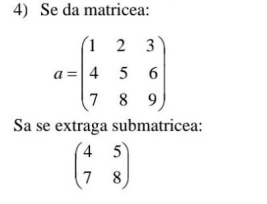

a=[1 2 3; 4 5 6; 7 8 9;];
submatrice=zeros(2);
submatrice(1,1)=a(2,1);
submatrice(1,2)=a(2,2);
submatrice(2,1)=a(3,1);
submatrice(2,2)=a(3,2);
disp(submatrice);

     4     5
     7     8



## Problema 5

a=eye(3);

## Problema 6

u=[1 2 3]

u =      1     2     3


v=[4 5 6]

v =      4     5     6


u<v

ans = 1×3 logical array
   1   1   1


u>v

ans = 1×3 logical array
   0   0   0


u<=v

ans = 1×3 logical array
   1   1   1


u>=v

ans = 1×3 logical array
   0   0   0


## Problema 7

u=[1 2 3];
v=[4 5 6];
u=2*u;
v=(-3)*v;
a=zeros(2,3);
a(1,:)=u;
a(2,:)=v;
disp(a)

     2     4     6
   -12   -15   -18



## Problema 8


$$\Bigg\{$$

$$\begin{array}{l}
x+3y+z=10\\
3x+2y+3z=16\\
2x+5y-2z=6
\end{array}$$


A = [1 3 1;
     3 2 3;
     2 5 -2;];

B = [10;
     16;
     6;];

AA=[1 3 1 10;

ans =      1
     2
     3


     3 2 3 16;
     2 5 -2 6;];


if rank(A)==rank(AA)

delta_x = [10 3 1;
           16 2 3;
           6 5 -2;];

delta_y = [1 10 1;
           3 16 3;
           2 6 -2;];

delta_z = [1 3 10;
           3 2 16;
           2 5 6;];

x=det(delta_x)/det(A)
y=det(delta_y)/det(A)
z=det(delta_z)/det(A)

end

!linsolve(A,B)

## Problema 9 si Problema 10

A = [1 4 7;
     2 5 8;
     3 6 9;];

B = [-1 3 -5;
     2 -2 2;
     1 -1 2;];
adunareMatrici(A,B)

ans =      0     7     2
     4     3    10
     4     5    11


scadereMatrici(A,B)

ans =      2     1    12
     0     7     6
     2     7     7


inmultireMatrici(A,B)

ans =     14   -12    17
    16   -12    16
    18   -12    15


cub(A)

ans =          468        1062        1656
         576        1305        2034
         684        1548        2412


produsMatrici(A,B)

ans =     -1    12   -35
     4   -10    16
     3    -6    18


impartireMatrici(A,B)

ans =    -1.0000    1.3333   -1.4000
    1.0000   -2.5000    4.0000
    3.0000   -6.0000    4.5000


patrat(A)

ans =      1    16    49
     4    25    64
     9    36    81


## Problema 11

## Functii

#### adunareMatrici

function rez=adunareMatrici(A,B)

 ztest  One-sample Z-test.
    H = ztest(X,M,SIGMA) performs a Z-test of the hypothesis that the data
    in the vector X come from a distribution with mean M, and returns the
    result of the test in H.  H=0 indicates that the null hypothesis
    ("mean is M") cannot be rejected at the 5% significance level.  H=1
    indicates that the null hypothesis can be rejected at the 5% level.  The
    data are assumed to come from a normal distribution with standard
    deviation SIGMA.
 
    X may also be a matrix or an N-D array.  For matrices, ztest performs
    separate Z-tests along each column of X, and returns a vector of
    results.  For N-D arrays, ztest works along the first non-singleton
    dimension of X.  M and SIGMA must be scalars.
 
    ztest treats NaNs as missing values, and ignores them.
 
    [H,P] = ztest(...) returns the p-value, i.e., the probability of
    observing 

    rez=A+B;
end

#### scadereMatrici

function rez=scadereMatrici(A,B)
    rez=A-B;
end

#### inmultireMatrici

function rez=inmultireMatrici(A,B)
    rez=A*B;
end

#### cub

function rez=cub(A)
    i=A*A;
    rez=i*A;
end

#### produsMatrici

function rez=produsMatrici(A,B)
    rez=A.*B;
end

#### impartireMatrici

function rez=impartireMatrici(A,B)
    rez=A./B;
end

#### patrat

function rez=patrat(A)
    rez=A.*A;
end